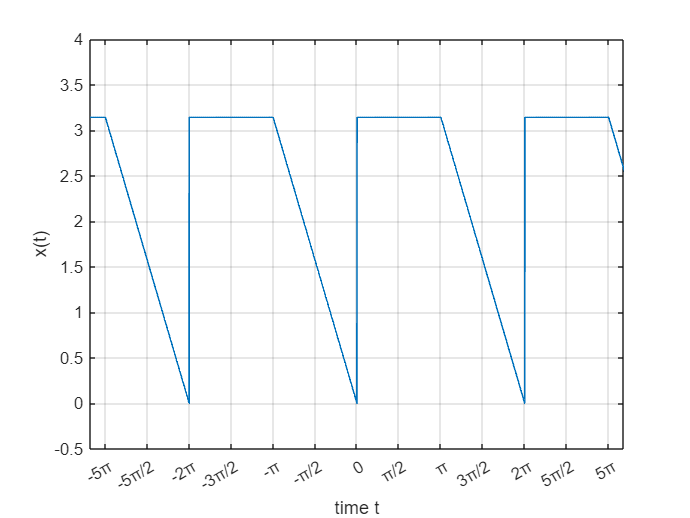

t = -5*pi:0.005:5*pi;

% Define x(t) function
u = @(a) (a>=0);
d = @(a) (a==0);
nslope = @(t) (-t).*(u(t-pi)-u(t-2*pi)) + 2*pi*(u(t-pi)-u(t-2*pi));
x = @(t) (mod(t,2*pi)<pi).*pi + (mod(t,2*pi)>=pi).*(mod(t,2*pi)<2*pi).*(nslope(mod(t,2*pi)));

plot(t, x(t),'LineWidth',1)
ylim([-0.5 4])
xlim([-10 10])
ylabel('x(t)')
xlabel('time t')
set(gca,'XTick',-3*pi:pi/2:3*pi)
set(gca,'XTickLabel',{'-5π','-5π/2','-2π','-3π/2','-π','-π/2','0','π/2','π','3π/2','2π','5π/2','5π'})
grid on;

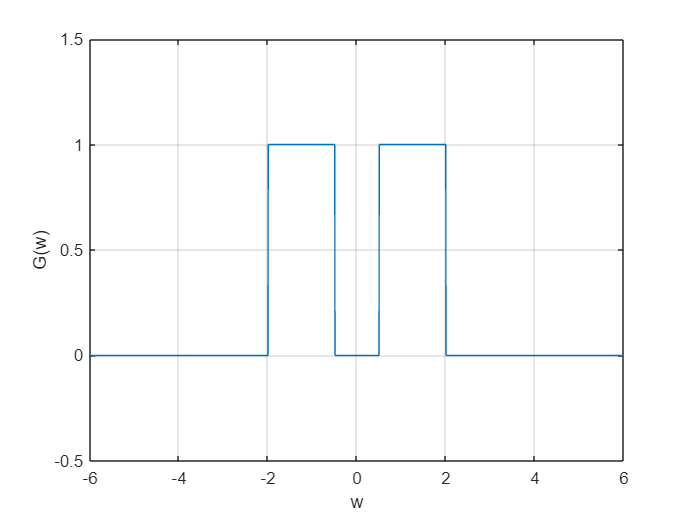


% Define angular frequencies for the range -6 ≤ ωo ≤ 6
w = -6:0.005:6;

G = @(w) (abs(w) >= 1/2).*(abs(w) < 2);
plot(w, G(w));
ylim([-0.5 1.5])
xlim([-6 6])
xlabel('w');
ylabel('G(w)');
grid on

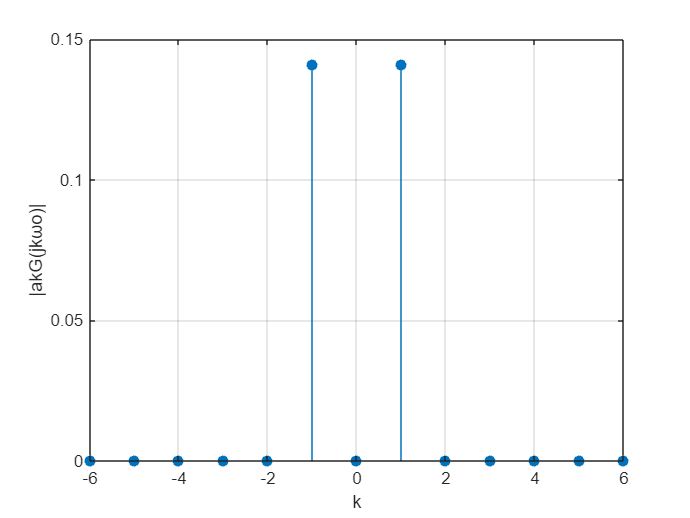


w0 = 1;

k = -6:6;
ak = @(k) 2*sin(k.*w0)/(k.*w0);
%ak = 1/(2*pi) * integral(@(t) x(t) .* exp(-j * w0 * t), -pi, pi);
magnitude_akG = @(a) abs(ak(k).*G(j.*a.*w0));

stem(k, magnitude_akG(k), "filled");
xlabel('k');
ylabel('|akG(jkωo)|');
grid on;

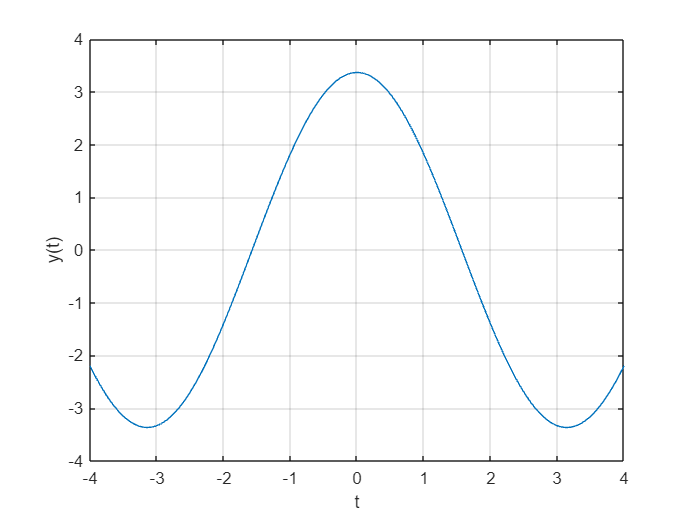


y = @(t) ak(-1)*exp(-j.*t)+ak(1)*exp(j.*t);
plot(t, real(y(t)));
ylim([-4 4])
xlim([-4 4])
xlabel('t');
ylabel('y(t)');
grid on;